clc;
clear;

 
% Newport initialization
dllPath = fullfile(pwd, "UsbDllWrap.dll");
asmInfo = NET.addAssembly(dllPath)

asmInfo =   NET.Assembly handle
  Package: NET

Properties for class NET.Assembly:

    AssemblyHandle
    Classes
    Structures
    Enums
    GenericTypes
    Interfaces
    Delegates


m_USB = Newport.USBComm.USB();
m_USB.OpenDevices();pause(1);
alDevInfoList = m_USB.GetDevInfoList ();pause(1);
m_nDeviceID = alDevInfoList.Item(0).ID;
buffer = System.Text.StringBuilder(65536);
bufferTemp = System.Text.StringBuilder(65536);
m_USB.Query(m_nDeviceID,"*IDN?",buffer);
buffer.ToString()

ans = NEWPORT 2931-C v2.1.0 04/28/09 SN10327


m_USB.Write(m_nDeviceID,"PM:RUN 1"); pause(1);
for i =2:-1:1
    m_USB.Write(m_nDeviceID,"PM:CHANnel "+num2str(i)); pause(0.2);
    m_USB.Write(m_nDeviceID,"PM:DS:BUFfer 0"); pause(0.2);
    m_USB.Write(m_nDeviceID,"PM:DS:SIZE 25000"); pause(0.2);
    m_USB.Write(m_nDeviceID,"PM:ANALOG:OUT 1"); pause(0.2);
    m_USB.Write(m_nDeviceID,"PM:Lambda 1550"); pause(0.2);
end


% Laser GBIP
% g1 = visadev("GPIB1::1::INSTR");
% writeread(g1,'*IDN?')

% Laser USB
dllPath = fullfile(pwd, "Santec_FTDI.dll");
asmInfo = NET.addAssembly(dllPath); pause(1);
TSL = Santec_FTDI.FTD2xx_helper("20060036"); pause(1);
TSL.Query('*IDN?')

ans = NR


TSL.Write('*CLS'); pause(0.1)
TSL.Write('*RST'); pause(0.1)

% Digilent AD2 setup
% clear("dq")
% daqreset()
% dq =  daq("digilent")
% dqch1=dq.addinput("AD2_0","ai0","Voltage");
% dqch2=dq.addinput("AD2_0","ai1","Voltage");
% dqch1.Range = [-2.5 2.5];
% dqch2.Range = [-2.5 2.5];
% dq.Rate = 100000;

Execute this code for fast 1pm resolution scanning

temp_wvStart = 1500

temp_wvStart = 1500

temp_wvEnd = 1630

temp_wvEnd = 1630

temp_wvRes = 0.0015

temp_wvRes = 0.0015

temp_wvSpeed = 1

temp_wvSpeed = 1

 
% Scan script settings
%PM settings
m_USB.Write(m_nDeviceID,"PM:CHANnel 2"); pause(0.5);
m_USB.Write(m_nDeviceID,"PM:MODE 0"); pause(0.1);
%m_USB.Write(m_nDeviceID,"PM:DS:SIZE 10000"); pause(0.5);
m_USB.Write(m_nDeviceID,"PM:ANALOGFILTER 1"); pause(0.1);
m_USB.Write(m_nDeviceID,"PM:AUTO 0"); pause(0.1);
m_USB.Write(m_nDeviceID,"PM:RANge 4"); pause(0.1);
% TSL settings
TSL.Write('*CLS'); pause(0.1)
TSL.Write('*RST'); pause(0.1)
TSL.Query('SM 1'); % Sweep Mode; 1-continous one way, 2-continous two ways, 3- step one way
pause(0.1); TSL.Query('SZ 1'); % Number of sweeps
pause(0.1); TSL.Query('TM 3'); % Trigger behaviour; 1-Start, 2-Stop, 3-Step
pause(0.1); TSL.Query("SS "+num2str(temp_wvStart,'%.4f')); % Start wavelength (nm)
pause(0.1); TSL.Query("SE "+num2str(temp_wvEnd,'%.4f')); % Stop wavelength (nm)
%pause(0.1); TSL.Query('SA 0'); % Time between sweeps (s)
%pause(0.1); TSL.Query('SB 0.1'); % Step time (s)
%pause(0.1); TSL.Query('WW 0.1'); % Step interval (nm)
pause(0.1); TSL.Query("SN "+num2str(temp_wvSpeed,'%.1f')); % Continous sweep speed (nm/s); [0.5:0.1:100]
pause(0.1); TSL.Query("TW "+num2str(temp_wvRes,'%.4f')); %0.0015 Trigger step (nm); [0.0001:0.0001:160] <1kHz
%TSL.Query("WA"+num2str(temp_wvStart,'%.4f')); pause(0.3)
wvs = temp_wvStart:temp_wvRes:temp_wvEnd;
scanTime = ceil((temp_wvEnd-temp_wvStart)/temp_wvSpeed)

scanTime = 130

clear('temp_wvEnd','temp_wvStart','temp_wvSpeed','temp_wvRes')

 
% Start Laser Sweep
clear("trigdata","outData")
pause(0.5);
TSL.Query('SG')

ans = 0000.0015


[data, startTime] = read(dq, (scanTime+4)*100000);

%plot(data.Time, data.AD2_0_ai1);
trigdata = data.AD2_0_ai1;
outData = data.AD2_0_ai0;
[pks,locs] = findpeaks(trigdata,"MinPeakHeight",(max(trigdata)+min(trigdata))/3,"MinPeakDistance",10);
out = outData(locs);
timeOut = milliseconds(data.Time);
timeOut = timeOut(locs);

% UpSample
locs2 = interp1(locs,1:0.25:length(locs),'linear');
out2 = interp1(outData,locs2,'linear');
wvs2 = interp1(locs,wvs.',locs2,'linear');

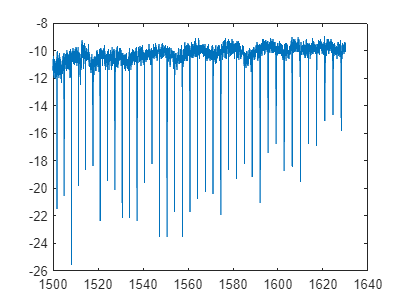

 
plot(wvs,10*log10(out/max(1)))

%plot(wvs2,10*log10(out2/max(out)))
%plot(wvs2,out2/max(out))
%plot(wvs,out)

% Wavelength sweep script SLOW, but precise
tic
%wvs = linspace(1550.7,1551,101);
wvs = 1549.6:0.0005:1550;
out = wvs*0;
%TSL.Query('SO'); pause(0.5) % Open Laser Shutter
for i=1:length(wvs)
     TSL.Query("WA"+num2str(wvs(i),'%.4f')); pause(0.05)
    for j=1:10
        tempAns = char(TSL.Query('SU'));
        if tempAns(end-1) == '0'
            break;
        end
        pause(0.01)
    end
    clear('tempAns')
    m_USB.Query(m_nDeviceID,"PM:DPower?",buffer);
    out(i) = double(string(buffer.ToString()));
end
%TSL.Query('SC'); pause(0.5) % Close Laser Shutter
toc

Elapsed time is 211.244815 seconds.


 
%PM continous scan
m_USB.Write(m_nDeviceID,"PM:CHANnel 1"); pause(1);
m_USB.Write(m_nDeviceID,"PM:MODE 0"); pause(0.1);
m_USB.Write(m_nDeviceID,"PM:AUTO 1"); pause(0.1);
m_USB.Write(m_nDeviceID,"PM:TRIG:START 0"); pause(0.1);
m_USB.Write(m_nDeviceID,"PM:TRIG:STOP 0"); pause(0.1);
m_USB.Write(m_nDeviceID,"PM:DS:ENable 0"); pause(0.1);
m_USB.Write(m_nDeviceID,"PM:ANALOGFILTER 2");

  

% Shut down USB devices
% m_USB.Write(m_nDeviceID,"PM:RUN 0"); pause(1);
m_USB.Write(m_nDeviceID,"PM:TRIG:START 1"); pause(0.5);
m_USB.Write(m_nDeviceID ,"PM:ANALOGFILTER 3"); pause(0.5);
if(exist('m_USB','var'))
    m_USB.CloseDevices();pause(1); % Newport
end 
if(exist('TSL','var'))
    TSL.CloseUsbConnection(); % Laser
end
clear;


% Service Code, Do not use!!!!!!!!!!!!!!!!!!!!!!!!

% temp = [out(1:ceil(length(out)/2)).';flip(out(ceil(length(out)/2)+1:end)).'];
temp1 = out(1:ceil(length(out)/2));
temp2 = flip(out(ceil(length(out)/2)+1:end));
if length(temp1)>length(temp2)
    temp2(length(temp1))=0;
end
temp = [temp1;temp2];
plot(temp(1:end-1))
% hold on
% plot(flip(out(ceil(length(out)/2)+1:end)))
% hold off

t = timer('TimerFcn',{@readPower,m_USB,m_nDeviceID,buffer},'Period',1,'ExecutionMode', 'fixedRate');
% t.TasksToExecute = 200;
% t.start()
 

function readPower(obj,evet,m_USB,m_nDeviceID,buffer)
    m_USB.Query(m_nDeviceID,"PM:DPower?",buffer);
    clc;
    double(string(buffer.ToString()))
end
